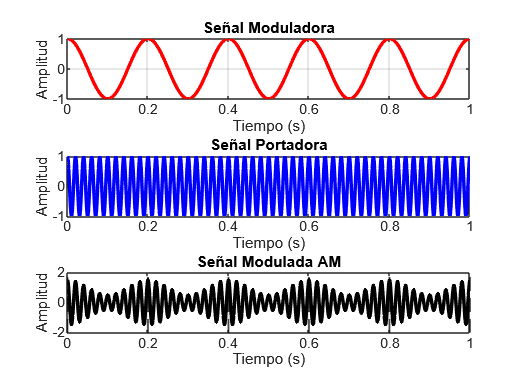

clc;    
clear;  
close all;

% --------------------------------
% 1. Definición de parámetros
% --------------------------------
fs = 1000;  % Frecuencia de muestreo (Hz)
t = 0:1/fs:1;  % Vector de tiempo (1 segundo de duración)
fc = 50;   % Frecuencia de la portadora (Hz)
fm = 5;    % Frecuencia de la señal moduladora (Hz)
A = 1;     % Amplitud de la portadora
m = 0.5;   % Índice de modulación (0 < m < 1 para evitar sobre modulación)

% --------------------------------
% 2. Generación de señales
% --------------------------------
moduladora = cos(2*pi*fm*t);  % Señal moduladora (mensaje)
portadora = A * cos(2*pi*fc*t);  % Señal portadora

% Modulación AM
AM = (1 + m * moduladora) .* portadora;

% --------------------------------
% 3. Representación gráfica
% --------------------------------
figure;

% -------------------------------
% Subplot 1: Señal moduladora
% -------------------------------
subplot(3,1,1);
plot(t, moduladora, 'r', 'LineWidth', 2);
xlabel('Tiempo (s)'); ylabel('Amplitud');
title('Señal Moduladora');
grid on;

% -------------------------------
% Subplot 2: Señal portadora
% -------------------------------
subplot(3,1,2);
plot(t, portadora, 'b', 'LineWidth', 2);
xlabel('Tiempo (s)'); ylabel('Amplitud');
title('Señal Portadora');
grid on;

% -------------------------------
% Subplot 3: Señal Modulada AM
% -------------------------------
subplot(3,1,3);
plot(t, AM, 'k', 'LineWidth', 2);
xlabel('Tiempo (s)'); ylabel('Amplitud');
title('Señal Modulada AM');
grid on;
hold on;

% Líneas verticales para separar ciclos de la portadora
for i = 0:1/fm:max(t)
    xline(i, '--k', 'LineWidth', 1);
end

hold off;